## Tarea 3

## Alejandro Brenes Calderón - C21319

## Eyeri Méndez Méndez - C24765

### **Desarrollo**

#### **1.**

#### **2.**

#### **3.**

a) 

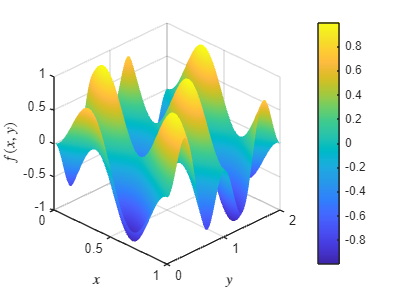

% Definimos los vectores requeridos
x = linspace(0, 1, 100);
y = linspace(0, 2, 200);

% Generamos la malla de puntos equidistantes
[xx, yy] = meshgrid(x, y);

% Definimos la función requerida
f = @(x, y) sin(2*pi*(x+y)) .* sin(pi*(x-y));

% Graficamos
figure;
surf(xx, yy, f(xx, yy));

% Mejoras en la visualización
shading interp; % Suaviza el sombreado
colorbar; % Añade una barra de color que indica los valores
view(45, 30); % Cambia el ángulo de vista
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$f(x, y)$', 'Interpreter', 'latex');
grid on;

b) 

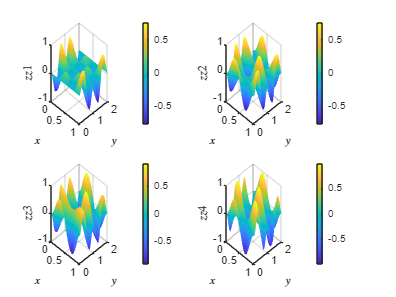

% Definimos la matriz zz
zz = f(xx, yy);

% Calculamos su descomposición en valores singulares
[U, S, V] = svd(zz);

% Guardamos los valores singulares
val_sing = diag(S);

% Calculamos las aproximaciones de rango 1, 2, 3 y 4
zz1 = val_sing(1) * U(:, 1) * V(:, 1)';
zz2 = zz1 + val_sing(2) * U(:, 2) * V(:, 2)';
zz3 = zz2 + val_sing(3) * U(:, 3) * V(:, 3)';
zz4 = zz3 + val_sing(4) * U(:, 4) * V(:, 4)';

% Graficamos las anteriores aproximaciones
figure;

subplot(2, 2, 1);
surf(xx, yy, zz1);
shading interp;
colorbar;
view(45, 30);
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$zz1$', 'Interpreter', 'latex');
grid on;

subplot(2, 2, 2);
surf(xx, yy, zz2);
shading interp;
colorbar;
view(45, 30);
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$zz2$', 'Interpreter', 'latex');
grid on;

subplot(2, 2, 3);
surf(xx, yy, zz3);
shading interp;
colorbar;
view(45, 30);
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$zz3$', 'Interpreter', 'latex');
grid on;

subplot(2, 2, 4);
surf(xx, yy, zz4);
shading interp;
colorbar;
view(45, 30);
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$zz4$', 'Interpreter', 'latex');
grid on;

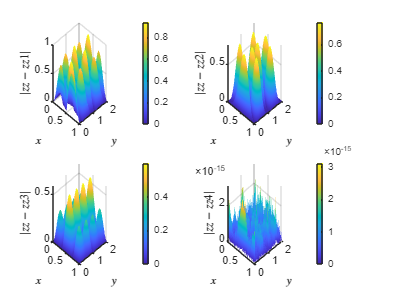


% Graficamos el error absoluto para cada aproximación
figure;

subplot(2, 2, 1);
surf(xx, yy, abs(zz - zz1));
shading interp;
colorbar;
view(45, 30);
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$|zz - zz1|$', 'Interpreter', 'latex');
grid on;

subplot(2, 2, 2);
surf(xx, yy, abs(zz - zz2));
shading interp;
colorbar;
view(45, 30);
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$|zz - zz2|$', 'Interpreter', 'latex');
grid on;

subplot(2, 2, 3);
surf(xx, yy, abs(zz - zz3));
shading interp;
colorbar;
view(45, 30);
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$|zz - zz3|$', 'Interpreter', 'latex');
grid on;

subplot(2, 2, 4);
surf(xx, yy, abs(zz - zz4));
shading interp;
colorbar;
view(45, 30);
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$|zz - zz4|$', 'Interpreter', 'latex');
grid on;

En los gráficos de las aproximaciones de rango 1, 2, 3 y 4 podemos ver que la aproximación por rango de la matriz **zz** inicia siendo mala y mejora conforme agregamos un rango más a la aproximación, como es de esperar. Con las aproximaciones de rango 3 y 4 podemos ver que hay poca o nula diferencia respecto al gráfico original de $f(x, y)$.

Respecto a los gráficos de los errores absolutos, se observa que el error disminuye conforme agregamos un rango más a la aproximación, complementando lo mencionado anteriormente de los gráficos de las aproximaciones por rango. Lo más relevante de estos últimos $4$ gráficos es que el error absoluto asociado a la aproximación de rango $4$ es muy pequeño, pues está en escala de $10^{-15}$, lo cual indica que esta aproximación es muy cercana a la matriz original **zz**; es decir, solo necesitamos los primeros $4$ valores singulares para replicar con una buena precisión la función $f(x, y)$.

c)

El rango de **zz **está dado por:

disp(rank(zz));

     4



Dado que el rango es $4$, la matriz tendrá $4$ valores singulares positivos y $96$ iguales a $0$.

Veamos si esto es cierto numéricamente usando código:

disp(sum(val_sing == 0));

     0




r = zeros(1, sum(val_sing > 0));

for i = 1:length(r)
    if val_sing(i) > 0
        r(i) = val_sing(i);
        disp(r(i));
    end
end

   35.7919

   35.4410

   35.0901

   35.0901

   3.1790e-14

   1.8952e-14

   1.7830e-14

   1.6726e-14

   1.5477e-14

   1.4612e-14

   1.2664e-14

   1.2120e-14

   1.1878e-14

   1.0854e-14

   1.0348e-14

   9.6574e-15

   9.4689e-15

   8.7769e-15

   8.4719e-15

   7.9815e-15

   7.6582e-15

   7.6408e-15

   7.5436e-15

   7.2806e-15

   6.4777e-15

   6.0700e-15

   5.8717e-15

   5.7246e-15

   5.2695e-15

   4.6528e-15

   4.5566e-15

   4.4588e-15

   3.6792e-15

   3.6547e-15

   3.5251e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.51

Como se puede apreciar, en términos numéricos la matriz cuenta con $4$ valores singulares positivos y el resto iguales a $0$, ya que el valor de estos últimos es casi igual a la precisión de la máquina, por lo que, al ser valores muy pequeños, se consideran $0$.

d)

Usando las siguientes identidades trigonométricas:


$$2 \cdot sin(x) \cdot sin(y) = cos(x-y) - cos(x+y)$$



$$cos(x + y) = cos(x) \cdot cos(y) - sin(x) \cdot sin(y)$$


Se tiene que:


$$g(x, y) = 2\cdot sin(2\pi (x+y)) \cdot sin(\pi(x-y)) = 2\cdot sin(2\pi \hspace{0.1mm} x+ 2\pi \hspace{0.1mm} y) \cdot sin(\pi \hspace{0.1mm} x- \pi \hspace{0.1mm} y) =$$



$$= cos(2\pi \hspace{0.1mm} x + 2\pi \hspace{0.1mm} y - (\pi \hspace{0.1mm} x - \pi \hspace{0.1mm} y)) - cos(2\pi \hspace{0.1mm} x + 2\pi \hspace{0.1mm} y + (\pi \hspace{0.1mm} x - \pi \hspace{0.1mm} y)) =$$



$$cos(\pi \hspace{0.1mm} x + 3\pi \hspace{0.1mm} y) - cos(3\pi \hspace{0.1mm} x + \pi \hspace{0.1mm} y) =$$



$$= cos(\pi \hspace{0.1mm} x) \cdot cos(3\pi \hspace{0.1mm} y) - sin(\pi \hspace{0.1mm} x) \cdot sin(3\pi \hspace{0.1mm} y) - [ cos(3\pi \hspace{0.1mm} x) \cdot cos(\pi \hspace{0.1mm} y) - sin(3\pi \hspace{0.1mm} x) \cdot sin(\pi \hspace{0.1mm} y)] =$$



$$= cos(\pi \hspace{0.1mm} x) \cdot cos(3\pi \hspace{0.1mm} y) - sin(\pi \hspace{0.1mm} x) \cdot sin(3\pi \hspace{0.1mm} y) - cos(3\pi \hspace{0.1mm} x) \cdot cos(\pi \hspace{0.1mm} y) + sin(3\pi \hspace{0.1mm} x) \cdot sin(\pi \hspace{0.1mm} y)$$



$$\Rightarrow f(x, y) = \frac{1}{2} \cdot g(x, y)$$


De esta manera, notamos que $f(x, y)$ se puede expresar como una suma de $4$ términos, donde cada uno corresponde al producto de una función de $x$ y una función de $y$, es decir, tenemos que:


$$f(x, y) = A(x) \cdot B(y) + C(x) \cdot D(y) + E(x) \cdot F(y) + G(x) \cdot H(y)$$


Esta forma sugiere que la matriz **zz**, que es la evaluación de $f(x, y)$ en la malla $(xx, yy)$, se puede descomponer en una suma de $4$ matrices, cada una de rango $1$.

Así, cada término de la suma que compone $f(x, y)$ contribuye con un rango a la matriz **zz**, por lo que esta cuenta rango $4$. Esto se debe a que cada uno de dichos términos representará una matriz de rango $1$ al evaluar $f(x, y)$ en $(xx, yy)$, pues cada término sería el producto de dos vectores, generando la matriz de rango $1$ mencionada.

Por lo tanto, al ser **zz** una matriz de rango 4, esta contará con $4$ valores singulares positivos y el resto iguales a $0$, tal y como se obtuvo en el inciso c).

#### **4.**

#### **5.**